# Computing  minimal cut sets

## Author: Susan Ghaderi, Luxembourg Centere for Systems Biomedicine 

## Reviewers: Sylvain Arreckx, Laurent Heirendt

## INTRODUCTION

During this tutorial, you will learn how to compute  cutsets for paths/cycles/elementary modes with Berge algorithm [1].

Elementary modes describe a feasible and balanced (steady state) flux distribution through the network, which is minimal with respect to utilized reactions (enzymes). The condition of being ‘minimal’ (elementary, non-decomposable, irreducible) is fundamental and means that removing any reaction in an elementary mode impedes the realization of a non-zero steady-state flux distribution (and therefore of a functionality) by means of the remaining reactions of the elementary mode. Now, assume that we want to prevent the production of metabolite X.  One strategy would be to inactivate (cut) one or several reactions in the network, e.g. by deleting the genes of certain enzymes or by other manipulations resulting in an inhibition of enzyme activity. This leads us to the definition of a cut set: a set of reactions a cut set (with respect to a defined objective reaction) if after the removal of these reactions from the network no feasible balanced flux. In other hands, a cut set for an objective reaction in a metabolic network is a set of reactions whose knockout disables flux through that reaction at steady state. Cut sets represent a particular type of failure mode of a metabolic network and may correspond to novel drug targets.

  The set of all feasible fluxes


$$K=\{ r \in R^n|Sr=0,r \geq 0, r\in Irr \}$$


is a polyhedral cone in $R^n$where $Irr$ is a set of irreversible reaction. A set of reactions $C$ subset of reactions, is a cut set for an objective $j\text{  }$among reactions, if 


$$r_c=0 ~leads~to ~r_j=0~\forall~r \in K$$


We present an algorithm which enable the computation of the elementary modes/extreme pathways in each network related to user-defined objective models and reactions.

## MATERIALS

- *Please ensure that the COBRA Toolbox has been properly installed and initialised. *

- *Also, you should install CNA (CellNetAnalyzer) software and initialise it. CNA web site (with manual): *[https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) 

## EQUIPMENT SETUP

Requirements for using CellNetAnalyzer are:

- MATLAB Version 7.5 (Release 18) or higher.

- some functions require an LP or (M)ILP solver; CNA supports the optimization toolbox of MATLAB, GLPKMEX, and CPLEX).

- More information can be found on: [https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html](https://www2.mpi-magdeburg.mpg.de/projects/cna/cna.html) where also a how-to tutorial on CellNetAnalyzer is provided.

## PROCEDURE 

*Before you start with these codes, you should initialise The COBRA Toolbox and CNA software by the following commands*

initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules ... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.
 > TranslateSBML is installed and working properly.
 > Configuring sol

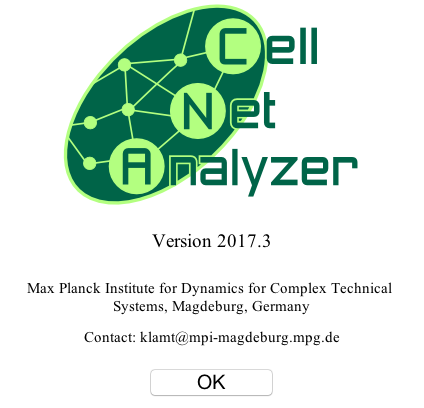

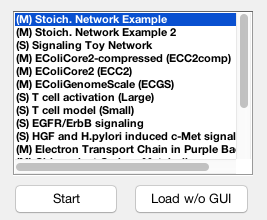

% Add path to Cell Net Analyzer
CNAPath = '~/CellNetAnalyzer';
addpath(genpath(CNAPath));
startcna

## Computing minimal cut set

The mandatory input in minimal cut set code is the set such as paths/cycles/elementary modes that you are going to compute its minimal cut set. To understand the meaning of all of the output you can type `help pathVectors`

% define the model
global CBTDIR
addpath([CBTDIR filesep 'tutorials' filesep 'minimalCutSets'])

load('efm.mat')
output = minimalCutSets(efm)

 
Computing minimal cut sets / hypergraph transversal
***************************************************
Found and removed 0 elements not contained in any mode.
 
Number of elements that cannot be deleted due to side constraints : 0
 
Number of admissable cut sets with 1 element : 1
 
2 equivalent elements found and removed
2 remaining elements
After 2 (of 2) iterations: 1 preliminary cut sets
 
Ready! Computation time: 0.12 sec
Longest list merge: 2.
Compressed MCS list length: 2.
 
Final result: 5 minimal cut sets
 


cutsets =      0     0     0     0     1
     1     0     1     0     0
     0     1     1     0     0
     1     0     0     1     0
     0     1     0     1     0


output =     cutsets: [5×5 double]


To understand the meaning of all of the output you can type `help pathVectors`

## TIMING

Running, the codes are dependent on the size of models may take long from 30 seconds to few hours. But in addition to the time of running you should consider between 60 seconds for start-up CNA software.

## ANTICIPATED RESULTS

The anticipated results is minimal cut set of every set which as an input.

## REFERENCES

[1] Klamt. S. and Gilles ED. Minimal cut sets in biochemical reaction networks. Bioinformatics. 20, 226–234 (2004).

[2] Klamt, S. et al.  Algorithmic approaches for computing elementary modes in large biochemical reaction networks. IEE Proc. Syst. Biol., 152, 249–255 (2005).